# butter_filter_digital

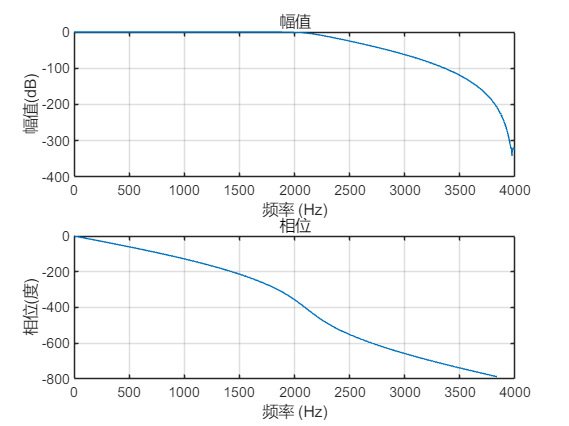

% 采样率 fN = 8000
% fp = 2100
% fs = 2500
% Rp = 3dB  通带内最大衰减
% Rs = 25dB 阻带内最小衰减
clear;
fN = 8000;
fp = 2100;
fs = 2500;
Rp = 3;
Rs = 25;
% 计算归一化频率
Ws = fs/(fN/2);
Wp = fp/(fN/2);

[n,Wn] = buttord(Wp,Ws,Rp,Rs);
[b,a] = butter(n,Wn);   % b是分子多项式系数，a是分母

freqz(b,a,1000,8000);